# Highlands Aquifer with precipitation and polar recharge

The high heat flow on early Mars may have lead to basal melting of the ice caps. This has been estimated to introduce > 10 km$^3$/yr into the Martian Highlands aquifer. Clifford and Parker (2001) modeled this as an inflow through the boundary condtion.

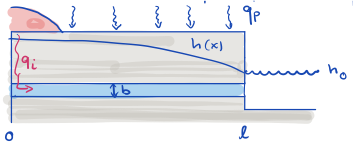

Assuming (for now) a steady linear confined aquifer we have the following model equations:

PDE: $-\frac{\mathrm{d}}{\mathrm{d}x}\left[bK\frac{\mathrm{d} h}{\mathrm{d}x}\right] = q_p$ on $x\in\left[0,\,l\right]$

BC's: $q_i=-K\left.\frac{\mathrm{d}h}{\mathrm{d}x}\right|_0$ $\Longrightarrow$$\left.\frac{\mathrm{d}h}{\mathrm{d}x}\right|_0 = -\frac{q_i}{K}$ and $h(l)=h_o$

## Dimensionless equations

Choosing the same dimesionless paramters as in the case without polar recharge

$x' = \frac{x}{l}$ and $h' = \frac{h-h_o}{q_p l^2/(bK)}$

we have the dimensionless problem

PDE: $-\frac{\mathrm{d}^2h'}{\mathrm{d}{x'}^2}=1$ on $x'\in \left[0,\,1\right]$

BC's: $\left.\frac{\mathrm{d}h'}{\mathrm{d}x'}\right|_0=\Pi$ and $h'(1)=0$.

which has one dimensionless parameter $\Pi=q_ib/(q_pl)$. The analytic solution is obtained by integrating twice and given by

$h' = \frac{1}{2}\left(1-{x'}^2\right)+\Pi (1-x')
$ and $q' = x'+\Pi$.

This family of solutions for differen values of $\Pi$ is shown in the figure.

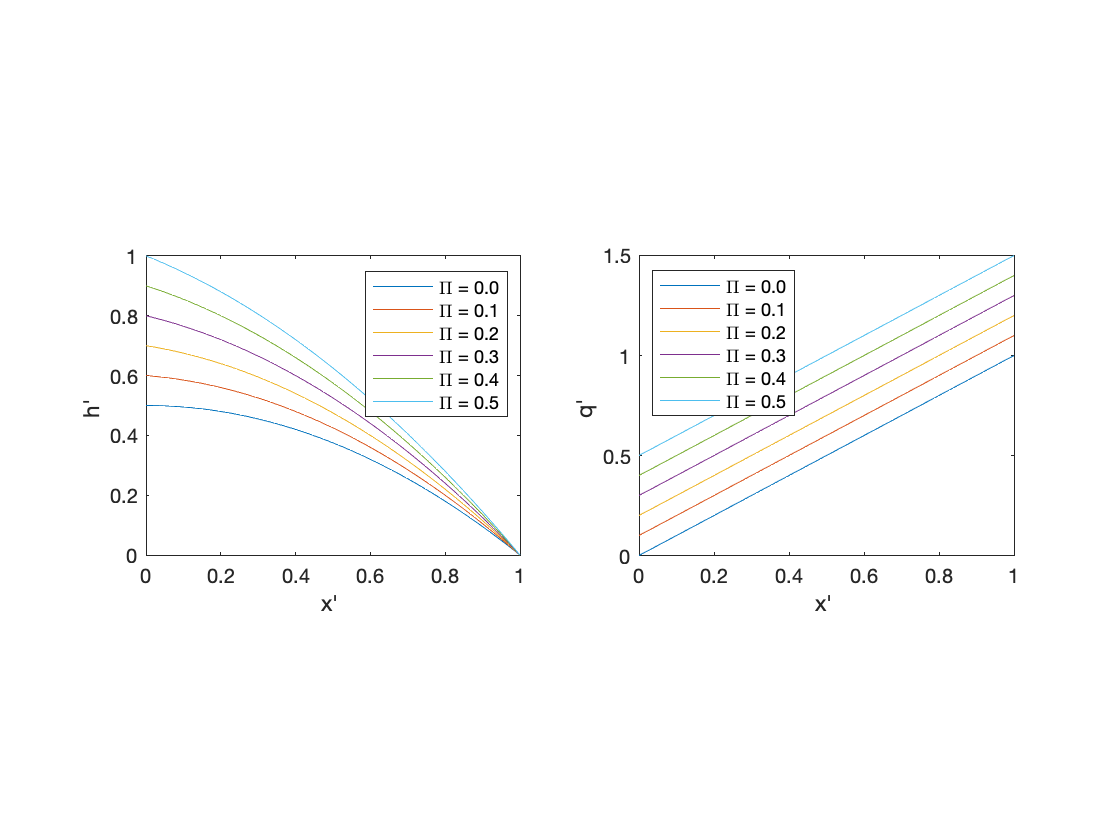

clear
q_ana = @(x,Pi) x + Pi;
h_ana = @(x,Pi) .5*(1-x.^2)+Pi*(1-x);

x_ana = linspace(0,1,1e2);

subplot 121
plot(x_ana,h_ana(x_ana,0)), hold on
plot(x_ana,h_ana(x_ana,0.1))
plot(x_ana,h_ana(x_ana,0.2))
plot(x_ana,h_ana(x_ana,0.3))
plot(x_ana,h_ana(x_ana,0.4))
plot(x_ana,h_ana(x_ana,0.5))
xlabel 'x'' ', ylabel 'h'' '
legend('\Pi = 0.0','\Pi = 0.1','\Pi = 0.2','\Pi = 0.3','\Pi = 0.4','\Pi = 0.5')
pbaspect([1 .8 1])

subplot 122
plot(x_ana,q_ana(x_ana,0)), hold on
plot(x_ana,q_ana(x_ana,0.1))
plot(x_ana,q_ana(x_ana,0.2))
plot(x_ana,q_ana(x_ana,0.3))
plot(x_ana,q_ana(x_ana,0.4))
plot(x_ana,q_ana(x_ana,0.5))
xlabel 'x'' ', ylabel 'q'' '
legend('\Pi = 0.0','\Pi = 0.1','\Pi = 0.2','\Pi = 0.3','\Pi = 0.4','\Pi = 0.5','location','northwest')
pbaspect([1 .8 1])

## Numerical solution

Here we apply the flux $Pi$ on the left hand boundary of the domain. Similar to the Dirichlet BC we specify the location and flux of the Neumann BC with the vectors `Grid.dof_neu` and `Grid.qb`, respectively.

Note, that `fn`, the r.h.s. vector arising from the Neumann BC, must be added to `fs` in the input to `solve_lbvp.m`.

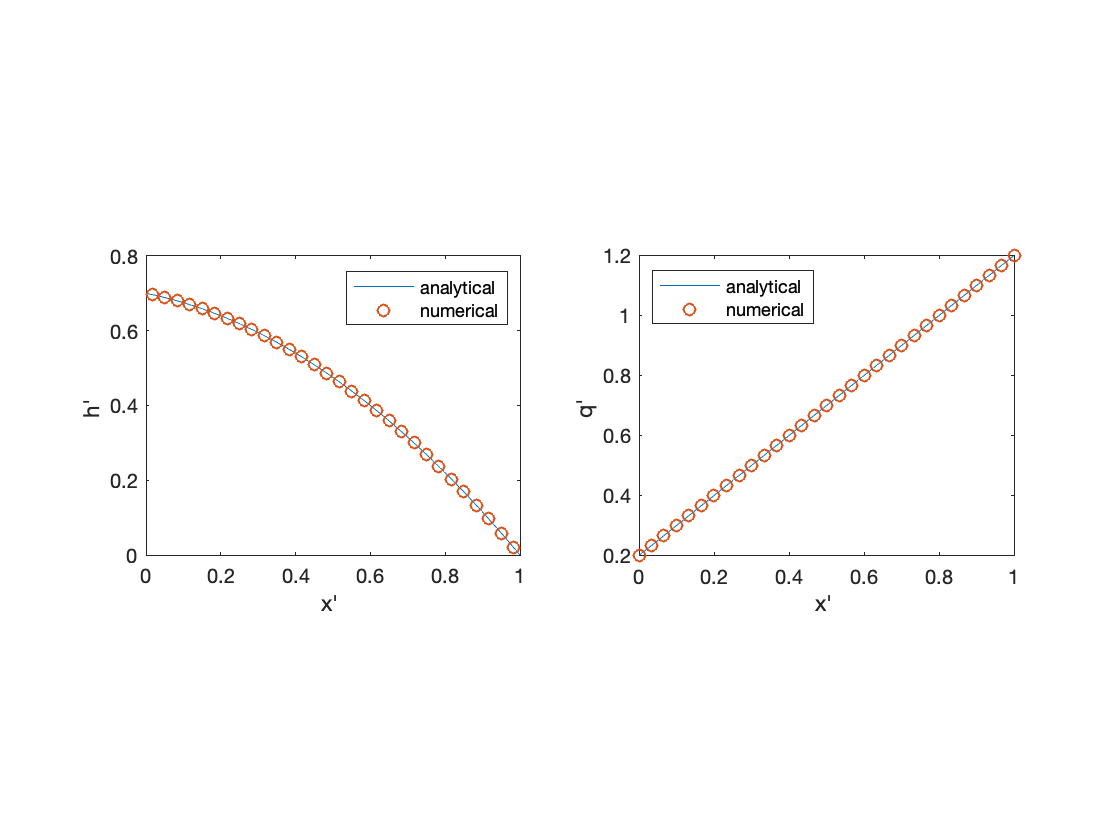

Pi = 0.2;
Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 30;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
L = -D*G; fs = ones(Grid.Nx,1);

BC.dof_dir = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = h_ana(Grid.xc(Grid.dof_xmax),Pi);

BC.dof_neu = Grid.dof_xmin;
BC.dof_f_neu = Grid.dof_f_xmin;
BC.qb = Pi;
[B,N,fn] = build_bnd(BC,Grid,I);

h = solve_lbvp(L,fs+fn,B,BC.g,N);
q = comp_flux(D,1,G,h,fs,Grid,BC);

figure
subplot 121
plot(x_ana,h_ana(x_ana,Pi)), hold on
plot(Grid.xc,h,'o')
xlabel 'x'' ', ylabel 'h'' '
legend('analytical','numerical')
pbaspect([1 .8 1])

subplot 122
plot(x_ana,q_ana(x_ana,Pi)), hold on
plot(Grid.xf,q,'o')
xlabel 'x'' ', ylabel 'q'' '
legend('analytical','numerical','location','northwest')
pbaspect([1 .8 1])

## Discrete conservation

Our equations are based on the balance of fluid mass and hence any convergent (=functioning) numerical solution should satisfy water balance in the limit of very fine resolution. By discrete conservation we mean the property of a numerical scheme to **satify the conservation exactly even on an arbitrarily coarse grid**! We can demonstrate this with the problem at hand. The outflow of groundwater into the northern ocean must exactly balance the input due to rain and polar recharge.

flux into ocean = flux due to polar recharge + precipitation added

In the analytic solution:

Flux due to polar recharge: $q'_r = \Pi$

Water added by precipitation: $q'_p = 1$

Flow rate of water into the ocean in: $q'_o=q'(1)= 1+\Pi$

Pi = 0.2;
Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 5;
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
L = -D*G; fs = ones(Grid.Nx,1);

BC.dof_dir = Grid.dof_xmax;
BC.dof_f_dir = Grid.dof_f_xmax;
BC.g = h_ana(Grid.xc(Grid.dof_xmax),Pi);

BC.dof_neu = Grid.dof_xmin;
BC.dof_f_neu = Grid.dof_f_xmin;
BC.qb = Pi;
[B,N,fn] = build_bnd(BC,Grid,I);

h = solve_lbvp(L,fs+fn,B,BC.g,N);
q = comp_flux(D,1,G,h,fs,Grid,BC);

q_o = q(Grid.dof_f_xmax)

q_o = 1.2000

1+Pi

ans = 1.2000

Even on a Grid with only 5 grid points the flux into the ocean is exactly $1+\Pi$!